# Calculation of viscosity of TEG

This script is evaluating the calculation of visocisty of TEG at low pressure, high pressure and in aqueous solution.

We start by defining a fluid of pure TEG using NeqSim

clear all;
fluid1 = thermo('cpa');
fluid1.addComponent('TEG', 1.0);

## Calculation of visocsity at low pressure

The viscosity of pure TEG from 0 °C up to 100 °C can be calulated using the script

i=1;
fluid1.setPressure(1.0, 'bara')
temperature = 0:10:100;

for temp = temperature
        fluid1.setTemperature(temp, 'C');
        TPflash(fluid1,0);
        visc = viscosity(fluid1);
        calcviscLP(i)=visc(1);
        i = i+1;
end

plot(temperature,calcviscLP)
xlabel('temperature [C]')
ylabel('Viscosity [cP]')
title('Viscosity of TEG at 1 atm')
hold off

## Viscosity of TEG at high pressure

Viscosity of TEG is known to increase with increasing pressure. This effec is illustrated in the script

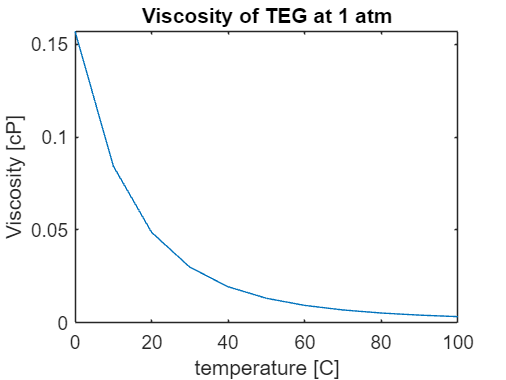

i=1;
pressure = [1 50 100 200];
temperature = 0:10:100;
j=1;
calcvisc = 0;
hold off;

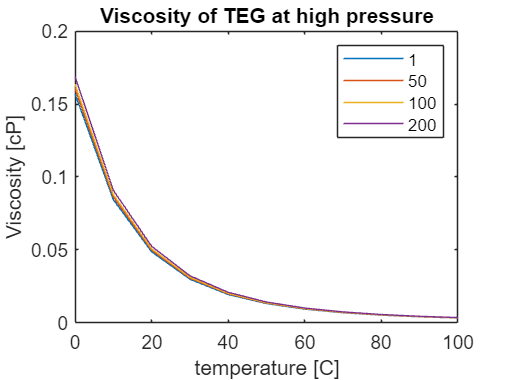

for pres = pressure
    fluid1.setPressure(pres, 'bara')
    i = 1;
    for temp = temperature 
        fluid1.setTemperature(temp, 'C');
        TPflash(fluid1,0);
        visc = viscosity(fluid1);
        calcvisc(j,i)=visc(1);
        i = i+1;
    end
    plot(temperature,calcvisc(j,:));
    hold on
    j = j+1;
end

xlabel('temperature [C]');
ylabel('Viscosity [cP]');
legend(string(pressure))
title('Viscosity of TEG at high pressure')
hold off

## Viscosity as function of water content in TEG

The viscosity of TEG will decrease when water is present. This is illuastrated in the script

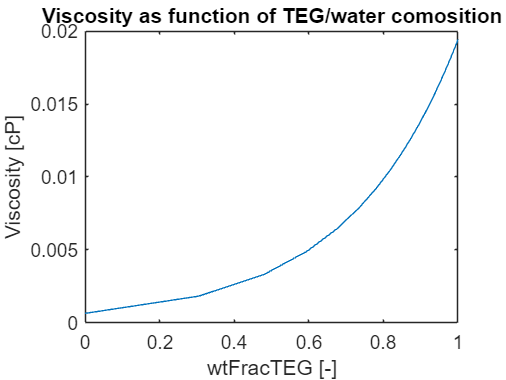

fluid1 = thermo('cpa');
fluid1.addComponent('TEG', 1.0);
fluid1.addComponent('water', 1.0);
fluid1.setMixingRule(10);
fluid1.setPressure(1.0, 'bara')
fluid1.setTemperature(40.0, 'C')

molfracwater = 0:0.05:1;
molfracTEG= 1:-0.05:0;

i=1;
for mol = molfracwater
        fluid1.setMolarComposition([molfracTEG(i) molfracwater(i)]);
        TPflash(fluid1,0);
        visc = viscosity(fluid1);
        calcviscAq(i)=visc(1);
        wtPrTEG(i) = fluid1.getPhase(0).getWtFrac(0);
        i = i+1;
end

plot(wtPrTEG,calcviscAq)
xlabel('wtFracTEG [-]')
ylabel('Viscosity [cP]')
title('Viscosity as function of TEG/water comosition')
hold off


plot(molfracTEG,calcviscAq)
xlabel('moleFracTEG [-]')
ylabel('Viscosity [cP]')
title('Viscosity as function of TEG/water comosition')
hold off

## Viscosity as function of pressure of natural gas

In the folowing script we investigate the effect of compined high pressure and gas sulubility. We will use a sysem of 50/50 mole% methane/TEG.

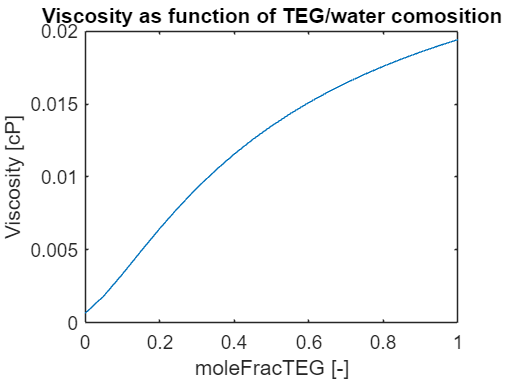

fluid2 = thermo('cpa');
fluid2.addComponent('methane', 0.1, "kg/sec");
fluid2.addComponent('water', 0.1, "kg/sec");
fluid2.addComponent('TEG', 0.9, "kg/sec");
fluid2.setMixingRule(10);
fluid2.setPressure(1.0, 'bara')
fluid2.setTemperature(40.0, 'C')

i=1;
pressure = [10 50 100 200];
temperature = 0:10:100;
j=1;
calcvisc = 0;
hold off;

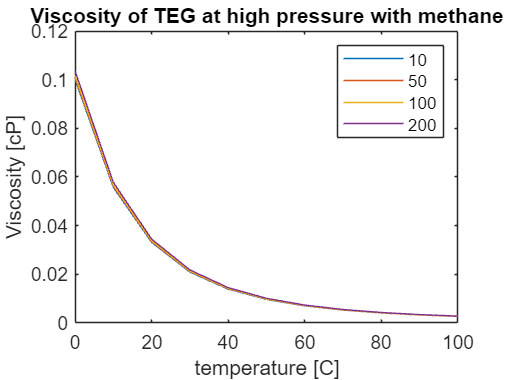

for pres = pressure
    fluid2.setPressure(pres, 'bara')
    i = 1;
    for temp = temperature 
        fluid2.setTemperature(temp, 'C');
        TPflash(fluid2,0);
        fluid2.initPhysicalProperties();
        visc = fluid2.getPhase('aqueous').getViscosity();
        calcvisc(j,i)=visc;
        i = i+1;
    end
    plot(temperature,calcvisc(j,:));
    hold on
    j = j+1;
end

xlabel('temperature [C]');
ylabel('Viscosity [cP]');
legend(string(pressure))
title('Viscosity of TEG at high pressure with methane')
hold off